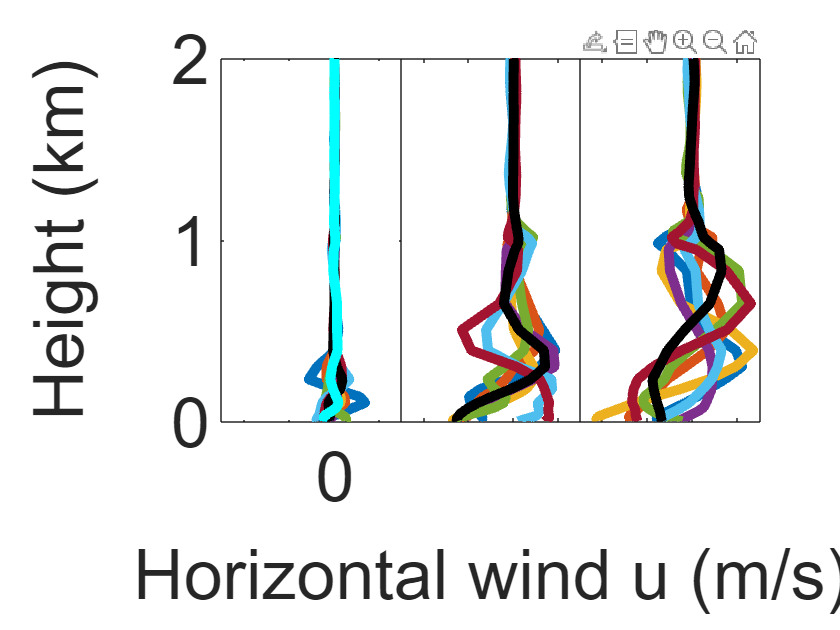

clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';

figure;
nn=tiledlayout(1,12,'TileSpacing','none');
tt1=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,13:18)=[];
            t(:,:,13:18)=[];
            wn(:,:,13:18)=[];
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    gravedad=1.352;
    timebar=1:1:time;
    ftv=0;  
    % Altura con el geopotencial
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    zi=400;     %Altura de la capa limite convectiva
    % lim=1.25;      %Hasta donde se grafica
    lim=2000;
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
    
sz= size(t(:,:,1:48)); %Redimensional
rs= reshape(u(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,2),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t %eliminar para no tener problemas con el tamaño
end
ylim([0 2]); %reescalar
xlim([-0.025 0.015])
hold off
yticks([])  %Alinear Y
tt2=nexttile([1, 4]);  %Siguiente subplot

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
    
sz= size(t(:,:,1:48));
rs= reshape(u(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,5),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([-0.025 0.015])
hold off

yticks([])
tt3=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    % ejex2=(-dis:dx:dis)/1000;            %En metros 
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
    
sz= size(t(:,:,1:48));
rs= reshape(u(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,8),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([-0.025 0.015])
hold off
% Modificaciones esteticas en los Ejes
tt1.YAxisLocation = 'left';
tt1.YTickMode = 'auto';
tt3.YTick = [];
tt2.YTick = [];
tt2.XTickLabels{1} = '';
tt3.XTickLabels{1} = '';
font=35;
tt1.FontSize = font;
tt2.FontSize = font;
tt3.FontSize = font;
linkaxes([tt1,tt2,tt3],'y')
xlabel(nn,'Horizontal wind u (m/s)','FontSize',font)
ylabel(nn,'Height (km)','FontSize',font)

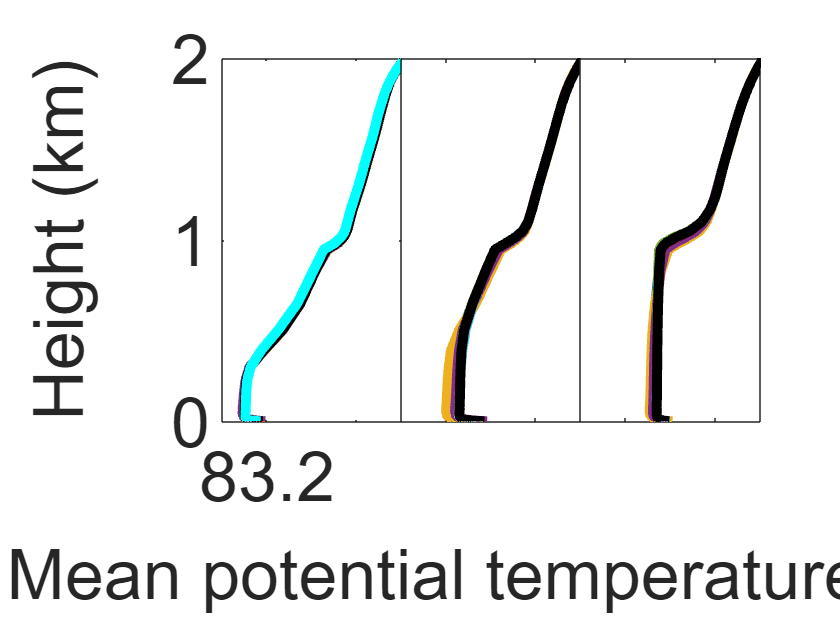


clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';

figure;
nn=tiledlayout(1,12,'TileSpacing','none');
tt1=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,13:18)=[];
            t(:,:,13:18)=[];
            wn(:,:,13:18)=[];
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    gravedad=1.352;
    timebar=1:1:time;
    ftv=0;  
    % Altura con el geopotencial
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    zi=400;     %Altura de la capa limite convectiva
    % lim=1.25;      %Hasta donde se grafica
    lim=2000;
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
    
sz= size(t(:,:,1:48)); %Redimensional
rs= reshape(t(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,2),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t %eliminar para no tener problemas con el tamaño
end
ylim([0 2]); %reescalar
xlim([83.1 83.5])
hold off
yticks([])  %Alinear Y
tt2=nexttile([1, 4]);  %Siguiente subplot

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
    
sz= size(t(:,:,1:48));
rs= reshape(t(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,5),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([83.1 83.5])
hold off

yticks([])
tt3=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    % ejex2=(-dis:dx:dis)/1000;            %En metros 
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
    
sz= size(t(:,:,1:48));
rs= reshape(t(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,8),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([83.1 83.5])
hold off
% Modificaciones esteticas en los Ejes
tt1.YAxisLocation = 'left';
tt1.YTickMode = 'auto';
tt3.YTick = [];
tt2.YTick = [];
tt2.XTickLabels{1} = '';
tt3.XTickLabels{1} = '';
font=35;
tt1.FontSize = font;
tt2.FontSize = font;
tt3.FontSize = font;
linkaxes([tt1,tt2,tt3],'y')
xlabel(nn,'Mean potential temperature (K)','FontSize',font)
ylabel(nn,'Height (km)','FontSize',font)

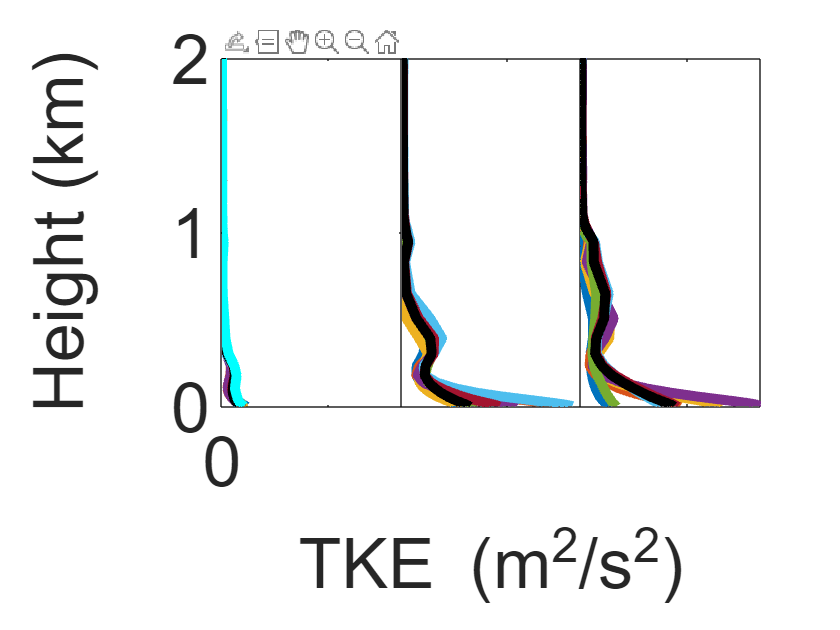

clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';

figure;
nn=tiledlayout(1,12,'TileSpacing','none');
tt1=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,13:18)=[];
            t(:,:,13:18)=[];
            wn(:,:,13:18)=[];
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    gravedad=1.352;
    timebar=1:1:time;
    ftv=0;  
    % Altura con el geopotencial
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    zi=400;     %Altura de la capa limite convectiva
    % lim=1.25;      %Hasta donde se grafica
    lim=2000;
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
KE=0.5.*((uprim.*uprim)+(wprim.*wprim));    
sz= size(t(:,:,1:48)); %Redimensional
rs= reshape(KE(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,2),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t %eliminar para no tener problemas con el tamaño
end
ylim([0 2]); %reescalar
xlim([0 0.0337])
hold off
yticks([])  %Alinear Y
tt2=nexttile([1, 4]);  %Siguiente subplot

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
KE=0.5.*((uprim.*uprim)+(wprim.*wprim));     
sz= size(t(:,:,1:48));
rs= reshape(KE(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,5),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([0 0.0337])
hold off

yticks([])
tt3=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    % ejex2=(-dis:dx:dis)/1000;            %En metros 
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
KE=0.5.*((uprim.*uprim)+(wprim.*wprim));     
sz= size(t(:,:,1:48));
rs= reshape(KE(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,8),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([0 0.0337])
hold off
% Modificaciones esteticas en los Ejes
tt1.YAxisLocation = 'left';
tt1.YTickMode = 'auto';
tt3.YTick = [];
tt2.YTick = [];
tt2.XTickLabels{1} = '';
tt3.XTickLabels{1} = '';
font=35;
tt1.FontSize = font;
tt2.FontSize = font;
tt3.FontSize = font;
linkaxes([tt1,tt2,tt3],'y')
xlabel(nn,'TKE ({m}^2/{s}^2)','FontSize',font)
ylabel(nn,'Height (km)','FontSize',font)

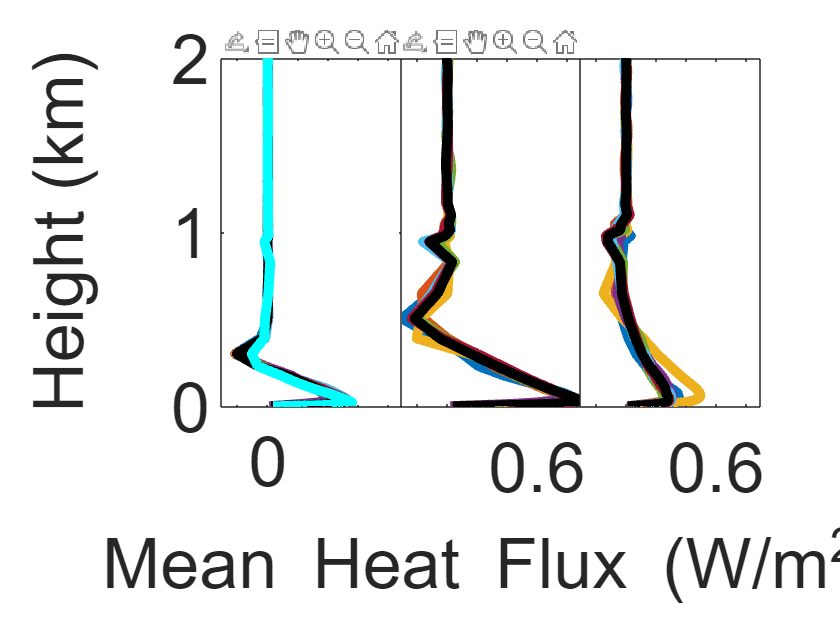

clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';

figure;
nn=tiledlayout(1,12,'TileSpacing','none');
tt1=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,13:18)=[];
            t(:,:,13:18)=[];
            wn(:,:,13:18)=[];
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    gravedad=1.352;
    timebar=1:1:time;
    ftv=0;  
    % Altura con el geopotencial
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    zi=400;     %Altura de la capa limite convectiva
    % lim=1.25;      %Hasta donde se grafica
    lim=2000;
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;

ehf=5940.*wprim.*tprim;    
sz= size(t(:,:,1:48)); %Redimensional
rs= reshape(ehf(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,2),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t %eliminar para no tener problemas con el tamaño
end
ylim([0 2]); %reescalar
xlim([-0.305 0.89])
hold off
yticks([])  %Alinear Y
tt2=nexttile([1, 4]);  %Siguiente subplot

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
ehf=5940.*wprim.*tprim;     
sz= size(t(:,:,1:48));
rs= reshape(ehf(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,5),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([-0.305 0.89])
hold off

yticks([])
tt3=nexttile([1, 4]);

for i=1:1:9
    switch i
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#0072BD';
       
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#D95319';
         
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#EDB120';
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='#4DBEEE';
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='k';
        case 9
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            un(:,:,22:29)=[];
            t(:,:,22:29)=[];
            wn(:,:,22:29)=[];
            yt='c';
        case 10
            Ar1=['p2_1'];
            Ar2=['p2_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=1001;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
            yt='m';    
        otherwise 
            Ar1=['p3_1'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            wn = squeeze(ncread(Ar1,Var3));
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    % ejex2=(-dis:dx:dis)/1000;            %En metros 
    gravedad=1.352;
    timebar=1:1:time;
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    ejez=ejez./1000;
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    wind=sqrt((u.^2)+(w.^2));
    uprom = mean(u,1);                 %Promedio en X
    uprom = repmat(uprom,length(wn(:,1,1)),1);       %Creamos una matriz con el vector resultante
    uprim = u-uprom;                  %Obtenemos la fluctuacion 
    tprom = mean(t,1);
    tprom = repmat(tprom,length(wn(:,1,1)),1);
    tprim = t-tprom;
    wprom = mean(w,1);
    wprom = repmat(wprom,length(wn(:,1,1)),1);
    wprim = w-wprom;
    windprom=mean(wind,1);
    windprom=repmat(windprom,length(wn(:,1,1)),1);
    windprim=wind-windprom;
ehf=5940.*wprim.*tprim;     
sz= size(t(:,:,1:48));
rs= reshape(ehf(:,:,1:48),sz(1),sz(2),[],8);
uprom1=mean(rs,3);
uprom2= squeeze(mean(uprom1,1));
pt=strcat('A',Ar1);
p=plot(uprom2(:,8),ejez,'DisplayName',pt,'LineWidth',5);
hold on
c = p.Color;
p.Color =yt;
clear u un w wn t 
end
ylim([0 2]);
xlim([-0.305 0.895])
hold off
% Modificaciones esteticas en los Ejes
tt1.YAxisLocation = 'left';
tt1.YTickMode = 'auto';
tt3.YTick = [];
tt2.YTick = [];
tt2.XTickLabels{1} = '';
tt3.XTickLabels{1} = '';
font=35;
tt1.FontSize = font;
tt2.FontSize = font;
tt3.FontSize = font;
linkaxes([tt1,tt2,tt3],'y')
xlabel(nn,'Mean Heat Flux (W/{m}^2)','FontSize',font)
ylabel(nn,'Height (km)','FontSize',font)